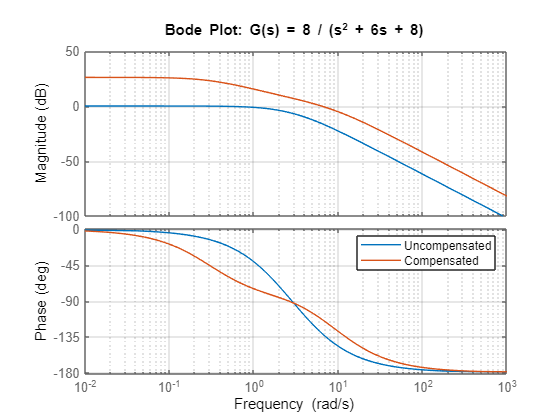

% ============================================================
% Case 8: G(s) = 8/(s^2 + 6s + 8)
% Author: Joshua Muthenya Wambua
% ============================================================

clc; clear; close all;
s = tf('s');

G = 8/(s^2 + 6*s + 8);
C_lead = 10*(s+2)/(s+10);
C_lag  = (s+3)/(s+0.3);
C_total = C_lead*C_lag;

T_uncomp = feedback(G,1);
T_comp = feedback(C_total*G,1);

figure;
bode(G, C_total*G); legend('Uncompensated','Compensated');
title('Bode Plot: G(s) = 8 / (s^2 + 6s + 8)'); grid on;

figure;
step(T_uncomp, T_comp);
legend('Uncompensated','Compensated');
title('Step Response: G(s) = 8 / (s^2 + 6s + 8)'); grid on;
% ============================================================
% Case 8: G(s) = 8/(s^2 + 6s + 8)
% Author: Joshua Muthenya Wambua
% ============================================================

clc; clear; close all;
s = tf('s');

G = 8/(s^2 + 6*s + 8);
C_lead = 10*(s+2)/(s+10);
C_lag  = (s+3)/(s+0.3);
C_total = C_lead*C_lag;

T_uncomp = feedback(G,1);
T_comp = feedback(C_total*G,1);

figure;
bode(G, C_total*G); legend('Uncompensated','Compensated');
title('Bode Plot: G(s) = 8 / (s^2 + 6s + 8)'); grid on;

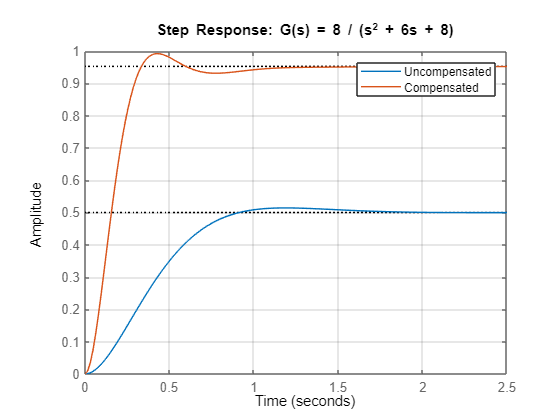


figure;
step(T_uncomp, T_comp);
legend('Uncompensated','Compensated');
title('Step Response: G(s) = 8 / (s^2 + 6s + 8)'); grid on;